# **OFDM Transmitter Testing senza codifica di canale**

Questo esempio mostra come progettare un trasmettitore OFDM (Orthogonal Frequency Division Multiplexing) per un canale SISO (Single-Input Single-Output) utilizzando una radio definita dal software (SDR).

Questo esempio descrive in dettaglio il protocollo di trasmissione a livello fisico del sistema OFDM che imita segnali di sincronizzazione tipici, simboli di riferimento, canali di controllo e canali dati. L'elaborazione del sistema di trasmissione OFDM include controllo di ridondanza ciclica (CRC), codifica, scrambling, codifica convoluzionale, modulazione, filtraggio, distorsione del canale.

L'esempio OFDM Receiver Using Software-Defined Radio riceve e demodula il segnale OFDM trasmesso da questo esempio.

## **Set OFDM Frame Parameters**

Imposta i parametri OFDM, tra cui la lunghezza FFT, la lunghezza del prefisso ciclico e il numero di sottoportanti. I parametri di spaziatura delle sottoportanti pilota e larghezza di banda del canale sono fissati rispettivamente a 30 KHz e 3 MHz.

Dopo aver configurato i parametri OFDM, devi impostare i parametri dei dati. Imposta l'ordine di modulazione, la velocità di codifica, il numero di simboli per frame e il numero di frame per trasmissione. I possibili schemi di modulazione sono BPSK, QPSK e 16-QAM e le possibili velocità di codifica sono 1/2 e 2/3. I parametri OFDM e i parametri dei dati devono essere comuni sia al trasmettitore che al ricevitore.

Puoi abilitare o disabilitare gli ambiti per la visualizzazione, tuttavia per simulazioni lunghe, si consiglia di disabilitare l'ambito. Per controllare l'output diagnostico, abilita o disabilita la verbosità in base alle necessità.

% The chosen set of OFDM parameters:
OFDMParams.FFTLength              = 128;   % lunghezza FFT
OFDMParams.CPLength               = 32;    % lunghezza Cyclic prefix 
OFDMParams.NumSubcarriers         = 72;    % numero di sottoportanti 
OFDMParams.Subcarrierspacing      = 3e3;   % spaziatura sottoportanti
OFDMParams.PilotSubcarrierSpacing = 9;     % spaziatura sottoportante pilot
OFDMParams.channelBW              = 3e5;   % larghezza di banda

% Data Parameters
dataParams.modOrder       = 256;   % tipo di modulazione
dataParams.numSymPerFrame = 25;   % numero di simboli per frame
dataParams.numFrames      = 10000;   % numero di frame da trasmettere
dataParams.enableScopes   = true;                    % visualizzatore dello spettro
dataParams.verbosity      = true;                    % ottenere i dati diagnostici

## Initialize Transmitter Parameters

Assegna il nome della radio che stai utilizzando per trasmettere il segnale OFDM alla variabile radioDevice. Imposta il guadagno del ricevitore e la frequenza del centro operativo.

centerFrequency        = 865e6;  % Center Frequency da 2.40 a 248
gain                   = -10;  % Set radio gain

La funzione helperOFDMSetParamsSDR inizializza i parametri comuni e specifici del trasmettitore/ricevitore richiesti per la simulazione OFDM, mentre la funzione helperGetRadioParams inizializza i parametri richiesti per la radio System Object™ del trasmettitore.

[sysParam,txParam,trBlk] = helperOFDMSetParamsSDR(OFDMParams,dataParams);
sampleRate               = sysParam.scs*sysParam.FFTLen;                % Sample rate of signal
ofdmTx                   = helperGetRadioParams(sysParam,sampleRate,centerFrequency,gain);

% Get the radio transmitter and spectrum analyzer system object system object for the user to visualize the transmitted waveform.
[radio,spectrumAnalyze] = helperGetRadioTxObj(ofdmTx);

## Generate Transmitter Waveform 

### **Transmit Frame Structure**

Un blocco di trasporto contiene dati utente e informazioni di controllo. Il trasmettitore OFDM trasmette un blocco di trasporto per frame. La dimensione del blocco di trasporto varia in base a diversi fattori: il numero di sottoportanti attive, il numero di sottoportanti pilota, l'ordine di modulazione, la velocità di codifica, la lunghezza CRC, la lunghezza del vincolo dell'encoder e il numero di simboli di dati per frame. La griglia di trasmissione popola segnali e canali su base per frame. La figura seguente mostra un frame di trasmissione di 28 simboli OFDM con lunghezza FFT di 128.

**Synchronization Symbol (SS)**

Un segnale di sincronizzazione (sync) viene trasmesso come primo simbolo nel frame. Il segnale di sincronizzazione è costituito da un segnale a 62 sottoportanti centrato su DC generato utilizzando uno ZadOff-Chu. Questo segnale è progettato per essere indipendente dalla larghezza di banda, il che significa che tutti i trasmettitori possono trasmettere questo segnale indipendentemente dalla larghezza di banda assegnata per quella cella. Il segnale è destinato a essere rilevato dai ricevitori per rilevare positivamente il segnale della cella e identificare il confine del frame (l'inizio del frame).

**Reference Symbol (RS)**

Il simbolo successivo nel frame di trasmissione è il simbolo di riferimento. Noto sia al trasmettitore che al ricevitore, il simbolo di riferimento consente al ricevitore di confrontare il simbolo di riferimento ricevuto con il simbolo di riferimento noto per stimare il canale. Il ricevitore compensa quindi la distorsione del canale tra il trasmettitore e il ricevitore.

**Header Symbol**

Il simbolo di intestazione trasmette la larghezza di banda, lo schema di modulazione della sottoportante e la velocità di codifica dei simboli di dati OFDM per aiutare il ricevitore a decodificare il frame trasmesso. Le informazioni sono abbastanza importanti da essere trasmesse con ampi margini di segnalazione e codifica per massimizzare la decodifica corretta. Pertanto, il simbolo è codificato a 1/2 velocità con ampia interlacciatura e modulato tramite BPSK. Poiché la distorsione del canale può cambiare nel tempo, il simbolo di intestazione viene trasmesso immediatamente dopo il simbolo di riferimento per massimizzare la probabilità di ricezione corretta. Poiché la larghezza di banda non è ancora nota, l'intestazione viene sempre trasmessa con un segnale a 72 sottoportanti centrato su DC.

**Pilot Signals**

Infine, per combattere l'instabilità di fase osservata a frequenze di trasmissione più elevate, un segnale pilota viene trasmesso a intervalli di sottoportante fissi all'interno dei simboli di dati per fornire un riferimento di fase al ricevitore.

**DC and Guard Subcarriers**

Le sottoportanti nulle al limite dello spettro di trasmissione vengono utilizzate per limitare l'energia spettrale a una larghezza di banda specificata. Anche la sottoportante in CC viene annullata per mantenere l'energia del segnale entro l'intervallo lineare dell'amplificatore di potenza.

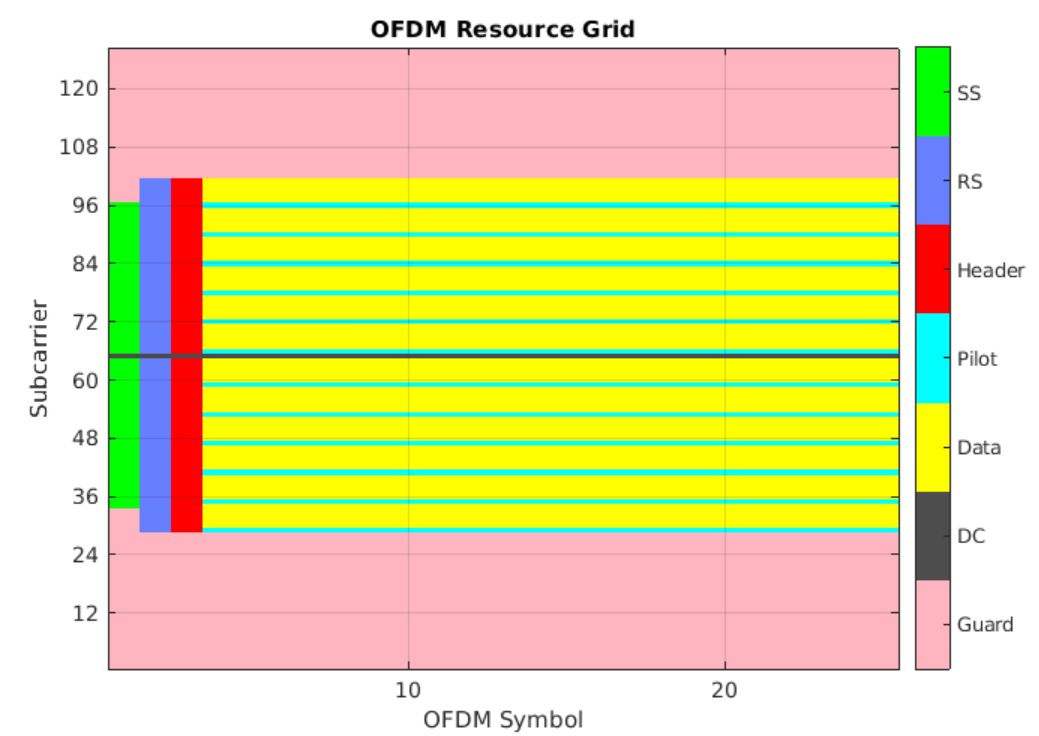

### Transmitter processing

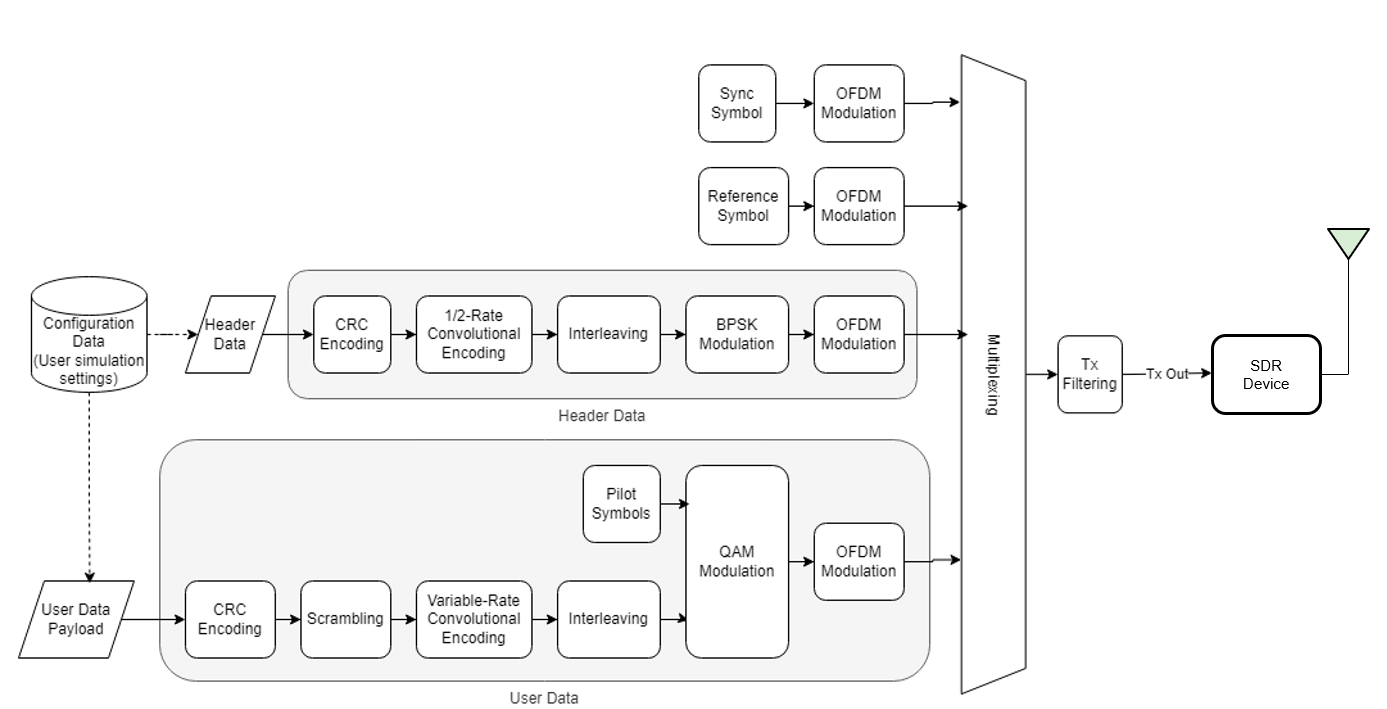

I simboli di dati comprendono un singolo utente che popola un singolo blocco di trasporto di dati trasmesso una volta per frame. Un oggetto comm.CRCGenerator calcola il CRC per il payload del blocco di trasporto e lo aggiunge al payload. I dati vengono codificati in modo additivo utilizzando un oggetto comm.PNSequence per distribuire la potenza dei dati in modo uniforme sullo spettro di trasmissione. L'interleaving viene eseguito con la funzione reshape per resistere agli errori di burst causati da dissolvenze profonde. La codifica convoluzionale aggiunge bit ridondanti per la correzione degli errori in avanti e viene eseguita con la funzione convenc. La perforazione dei dati aumenta la produttività dei dati riducendo il numero di bit ridondanti. Il blocco di trasporto viene modulato utilizzando la funzione qammod ed è pronto per la trasmissione in un frame OFDM. Tutti i segnali vengono modulati OFDM utilizzando la funzione ofdmmod. Il segnale viene filtrato per ridurre le emissioni fuori banda utilizzando dsp.FIRFilter, con coefficienti generati utilizzando le funzioni di progettazione del filtro firpmord e firpm.

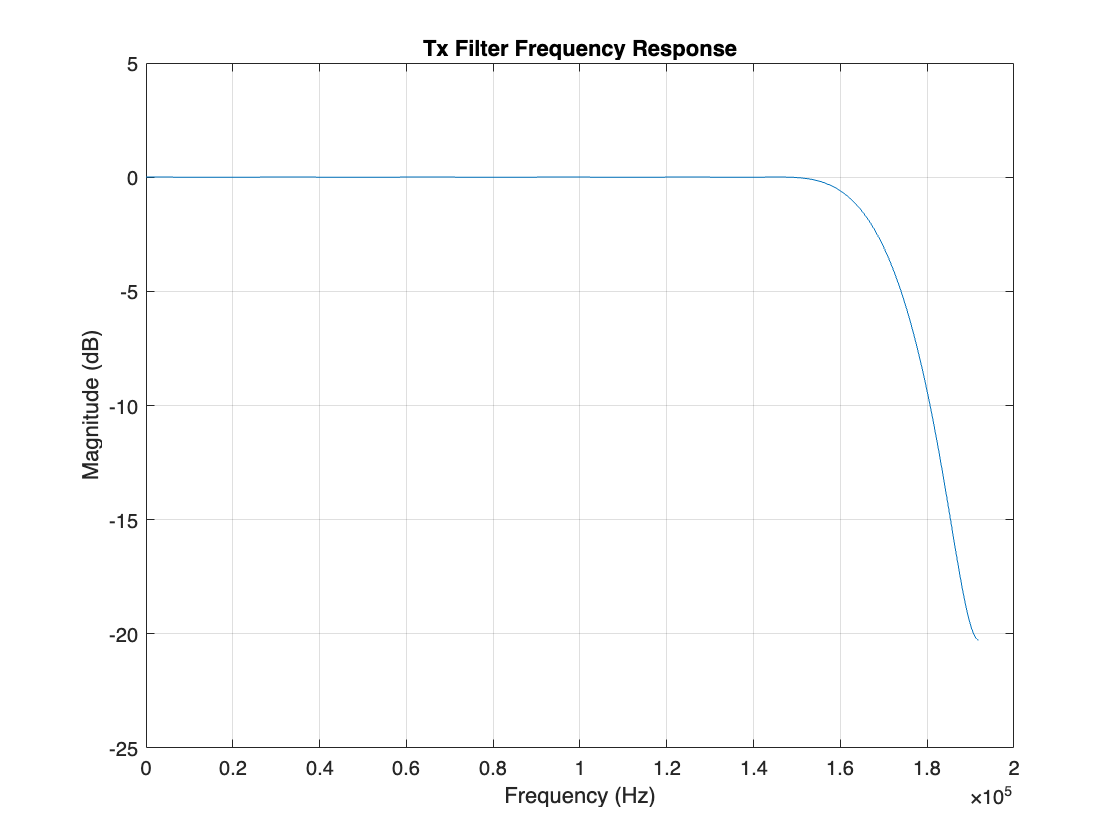


% Initialize transmitter
txObj = helperOFDMTxInit(sysParam);

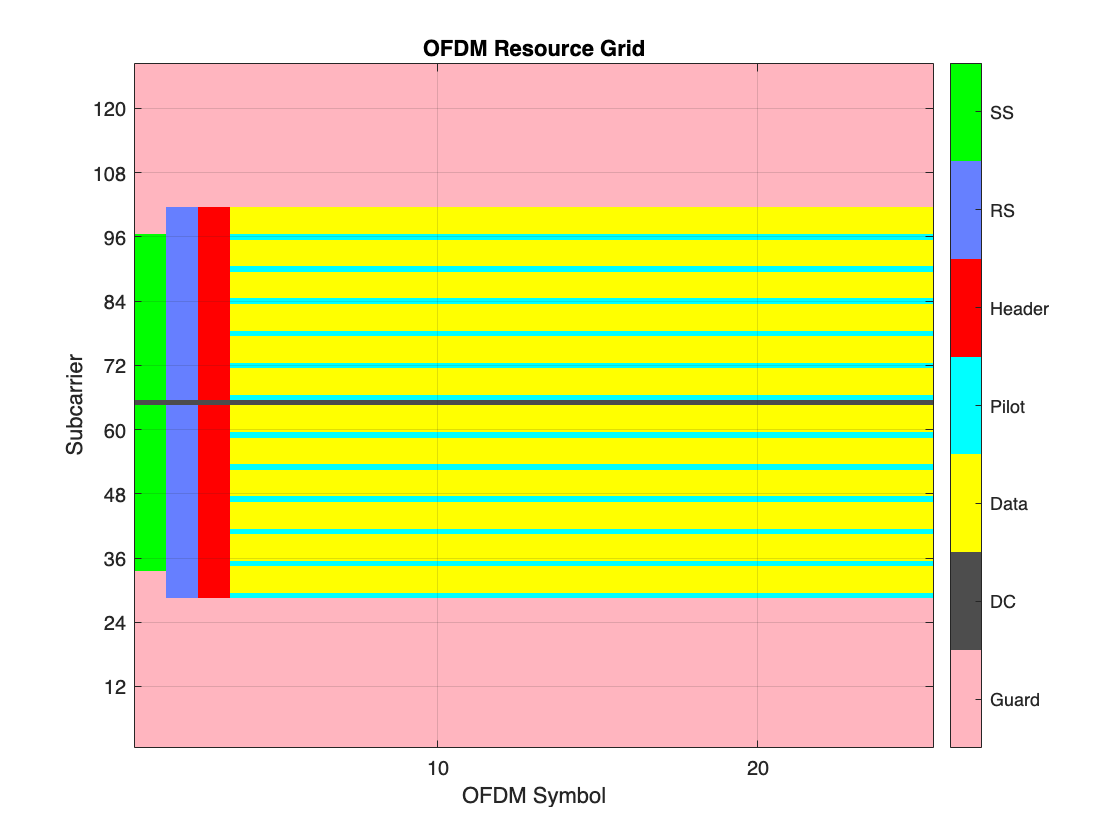

tunderrun = 0; % Initialize count for underruns

% A known payload is generated in the function helperOFDMSetParams with
% respect to the calculated trBlkSize
% Store data bits for BER calculations
txParam.txDataBits = trBlk;
[txOut,txGrid,txDiagnostics] = helperOFDMTx(txParam,sysParam,txObj);

% Display the grid if verbosity flag is enabled
if dataParams.verbosity
    helperOFDMPlotResourceGrid(txGrid,sysParam);
end

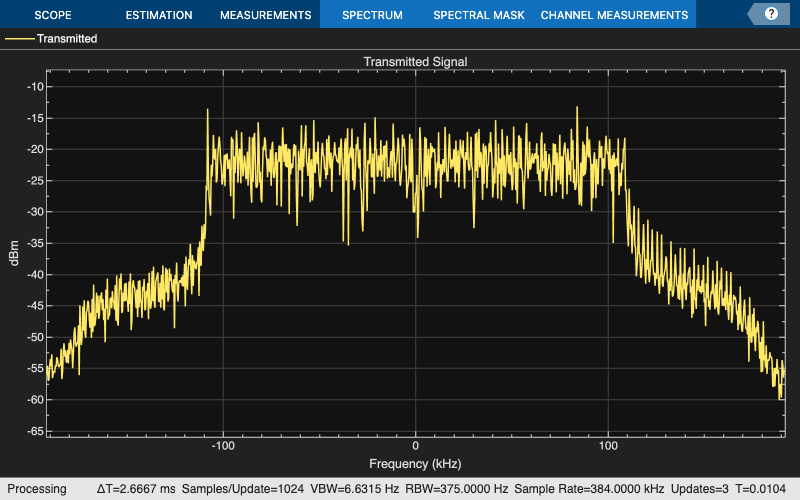


% Repeat the data in a buffer for PLUTO radio to make sure there are less
% underruns. The receiver decodes only one frame from where the first
% synchroization signal is received
txOutSize = length(txOut);
if txOutSize < 48000
    frameCnt = ceil(48000/txOutSize);
    txWaveform = zeros(txOutSize*frameCnt,1);
    for i = 1:frameCnt
        txWaveform(txOutSize*(i-1)+1:i*txOutSize) = txOut;
    end
else
    txWaveform = txOut;
end
txWaveform=0.7*txWaveform./(max(abs(txWaveform)));
if dataParams.enableScopes
    spectrumAnalyze(txOut);
end

## Transmit Over Radio

for frameNum = 1:sysParam.numFrames+1
    underrun = radio(txWaveform);
    tunderrun = tunderrun + underrun;  % Total underruns
end

## Establishing connection to hardware. This process can take several seconds.


% Clean up the radio System object
release(radio);

% Copyright 2023 The MathWorks, Inc.